clear;
dataFolder = fullfile(tempdir,"turbofan");
if ~exist(dataFolder,'dir')
    mkdir(dataFolder);
end
filename = matlab.internal.examples.downloadSupportFile("nnet","data/TurbofanEngineDegradationSimulationData.zip");
unzip(filename,dataFolder)

filenamePredictors = fullfile(dataFolder,"train_FD001.txt");
[XTrain,YTrain] = processTurboFanDataTrain(filenamePredictors);

m=min([XTrain{:}],[],2);
M=max([XTrain{:}],[],2);
idxConstant=M==m;

for i =1:numel(XTrain)
    XTrain{i}(idxConstant,:)=[];
end

numFeatures=size(XTrain{1},1)

numFeatures =     17


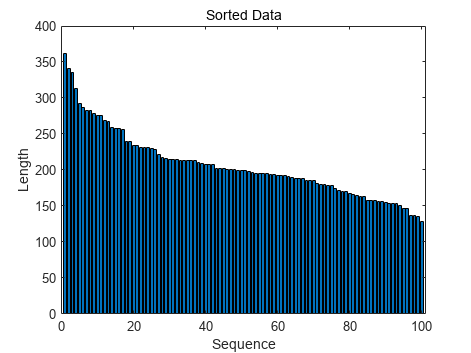

mu=mean([XTrain{:}],2);
sig=std([XTrain{:}],0,2);

for i = 1:numel(XTrain)
    XTrain{i} = (XTrain{i} - mu) ./ sig;
end

thr = 150;
for i = 1:numel(YTrain)
    YTrain{i}(YTrain{i} > thr) = thr;
end

for i=1:numel(XTrain)
    sequence = XTrain{i};
    sequenceLengths(i) = size(sequence,2);
end

[sequenceLengths,idx] = sort(sequenceLengths,'descend');
XTrain = XTrain(idx);
YTrain = YTrain(idx);

figure
bar(sequenceLengths)
xlabel("Sequence")
ylabel("Length")
title("Sorted Data")

miniBatchSize=20;

numResponses=size(YTrain{1},1)

numResponses =      1


numHiddenUnits=200;

layer=[
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits,'OutputMode','sequence')
    fullyConnectedLayer(50)
    dropoutLayer(0.5)
    fullyConnectedLayer(numResponses)
    regressionLayer]

layer =   具有以下层的 6×1 Layer 数组:

     1   ''   序列输入   序列输入: 17 个维度
     2   ''   LSTM     LSTM: 200 个隐藏单元
     3   ''   全连接     50 全连接层
     4   ''   丢弃      50% 丢弃
     5   ''   全连接     1 全连接层
     6   ''   回归输出   mean-squared-error

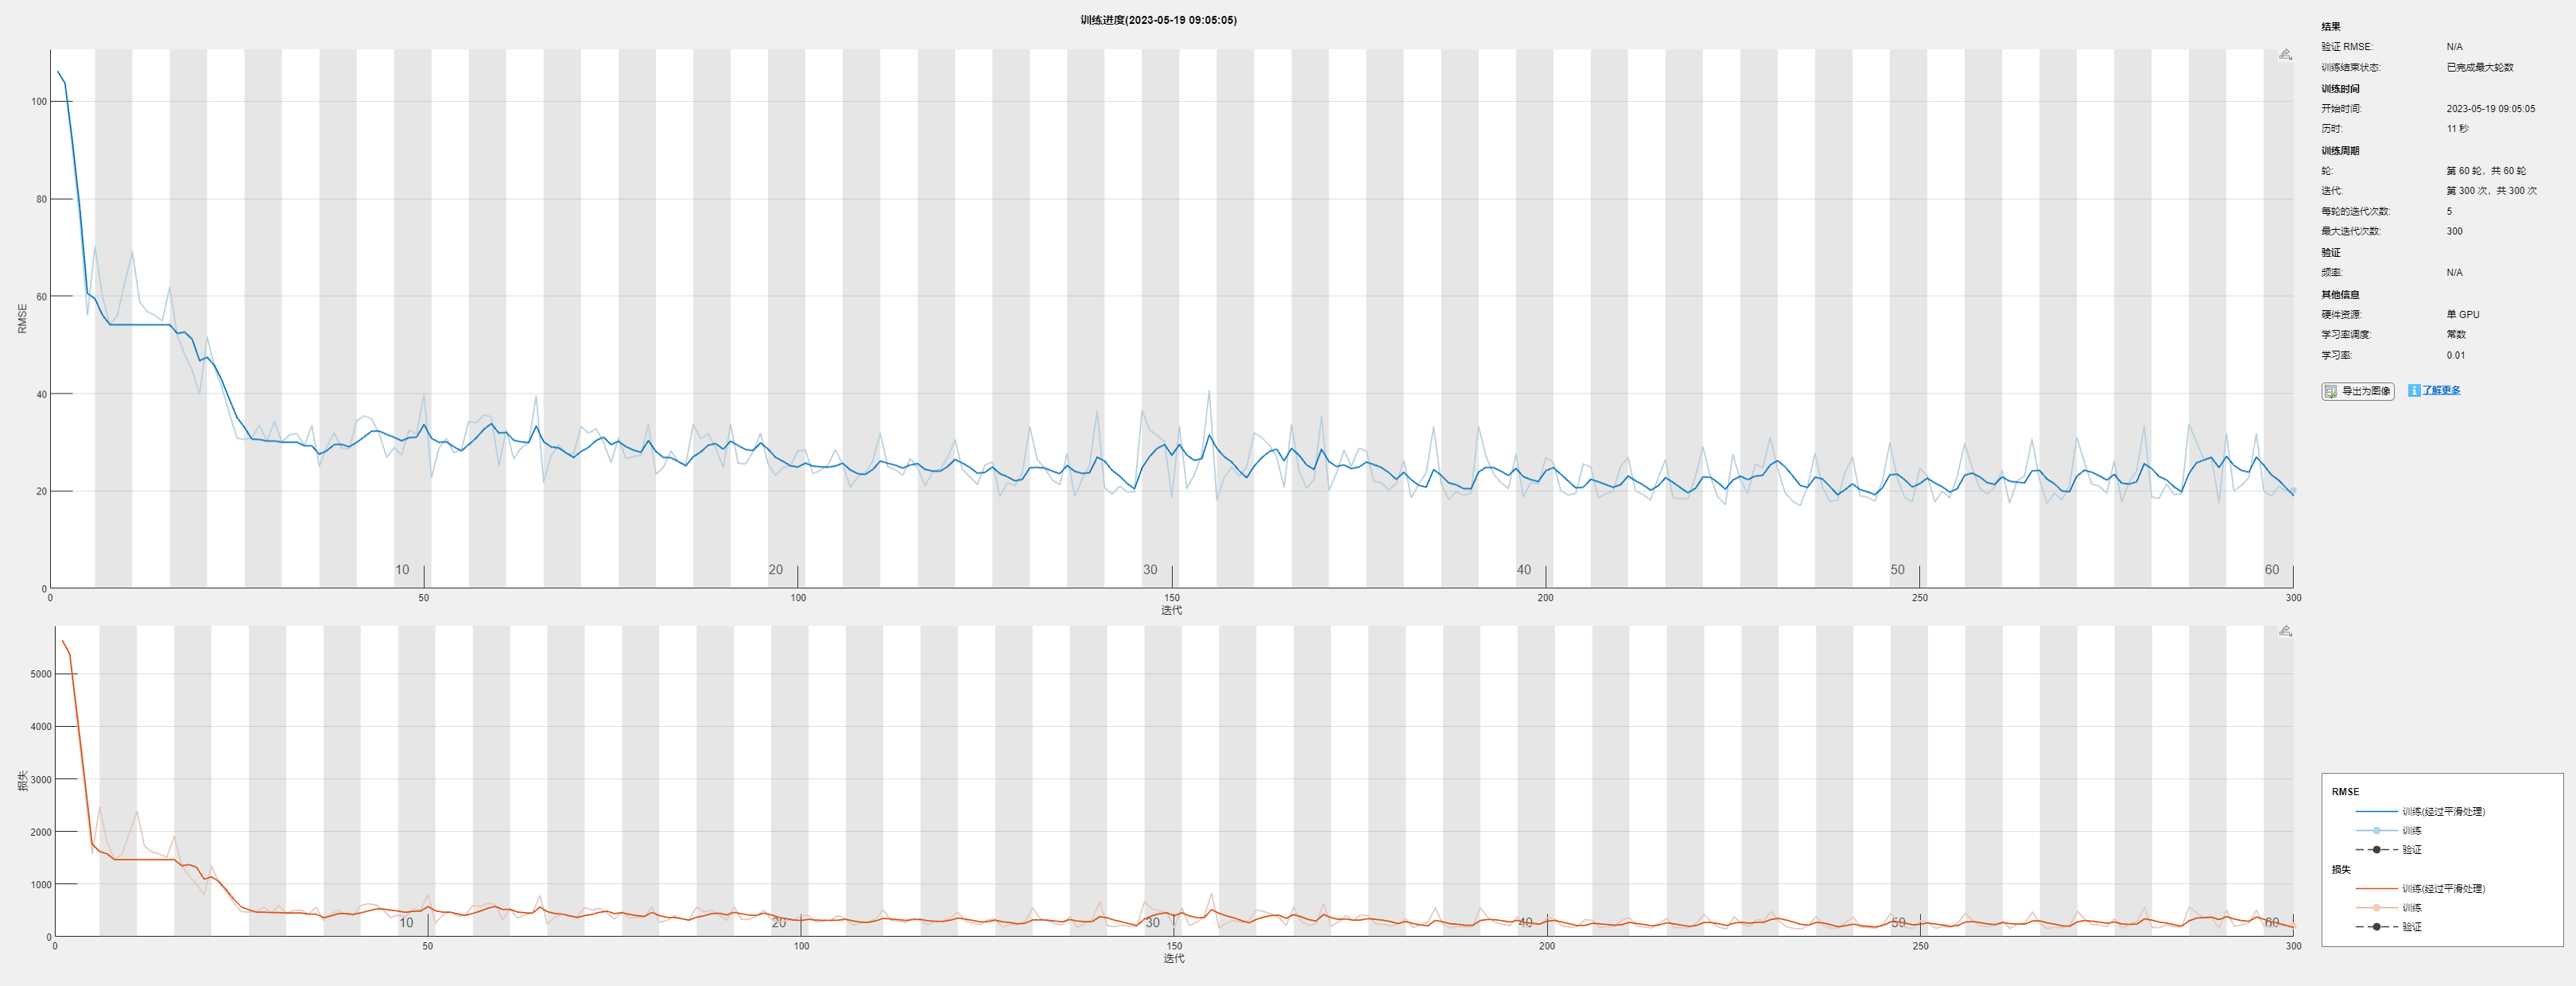


maxEpochs = 60;
miniBatchSize = 20;

options = trainingOptions('adam', ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'InitialLearnRate',0.01, ...
    'GradientThreshold',1, ...
    'Shuffle','never', ...
    'Plots','training-progress',...
    'Verbose',0);

net=trainNetwork(XTrain,YTrain,layer,options);

filenamePredictors=fullfile(dataFolder,'test_FD001.txt');
filenameResponses=fullfile(dataFolder,'RUL_FD001.txt');
[XTest,YTest]=processTurboFanDataTest(filenamePredictors,filenameResponses);

for i = 1:numel(XTest)
    XTest{i}(idxConstant,:) = [];
    XTest{i} = (XTest{i} - mu) ./ sig;
    YTest{i}(YTest{i} > thr) = thr;
end
YPred = predict(net,XTest,'MiniBatchSize',1)

YPred = 100×1 cell 数组
    {[                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                            

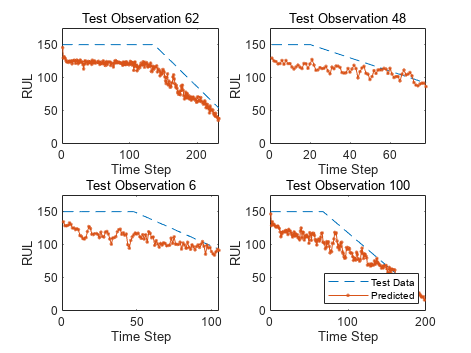

idx = randperm(numel(YPred),4);
figure
for i = 1:numel(idx)
    subplot(2,2,i)
    
    plot(YTest{idx(i)},'--')
    hold on
    plot(YPred{idx(i)},'.-')
    hold off
    
    ylim([0 thr + 25])
    title("Test Observation " + idx(i))
    xlabel("Time Step")
    ylabel("RUL")
end
legend(["Test Data" "Predicted"],'Location','southeast')

for i = 1:numel(YTest)
    YTestLast(i) = YTest{i}(end);
    YPredLast(i) = YPred{i}(end);
end
figure
rmse = sqrt(mean((YPredLast - YTestLast).^2))

rmse = single
       21.439


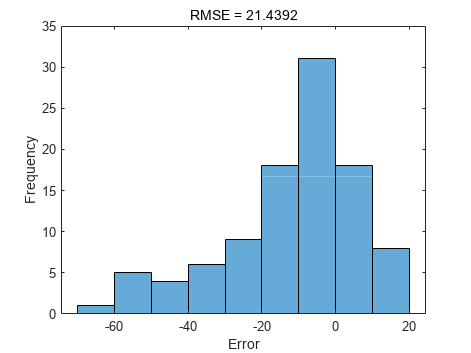

histogram(YPredLast - YTestLast)
title("RMSE = " + rmse)
ylabel("Frequency")
xlabel("Error")